# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 5;
threshold = 0.6;

## Generate a random physical topology

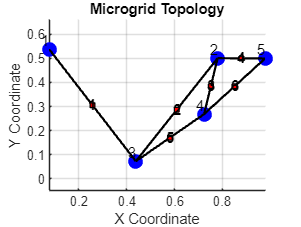

Coordinates of DGs:
    0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999

Adjacency Matrix:
     0     0     1     0     0
     0     0     1     1     1
    -1    -1     0     1     0
     0    -1    -1     0     1
     0    -1     0    -1     0

B_il Matrix:
     1     0     0     0     0     0
     0     1     1     1     0     0
    -1    -1     0     0     1     0
     0     0    -1     0    -1     1
     0     0     0    -1     0    -1



coords =     0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999


adjMatrix =      0     0     1     0     0
     0     0     1     1     1
    -1    -1     0     1     0
     0    -1    -1     0     1
     0    -1     0    -1     0


B_il =      1     0     0     0     0     0
     0     1     1     1     0     0
    -1    -1     0     0     1     0
     0     0    -1     0    -1     1
     0     0     0    -1     0    -1


% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.

[coords, adjMatrix, B_il] = generateMicrogridTopology(numOfDGs, threshold)

## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.0022;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance

for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0);
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i})
end

PVal =     3.3057   10.8912   -3.5611
   10.8912   65.1215  -11.8465
   -3.5611  -11.8465   13.0624


KVal =  -198.5477   11.4024   -3.8502


LVal =  -159.8798   22.6717  -23.3203


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.3865   11.0239   -3.6268
   11.0239   65.1182  -11.9119
   -3.6268  -11.9119   13.1630


KVal =  -225.3763   11.2072   -3.8700


LVal =  -177.1814   25.3854  -26.1402


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.4959   11.1825   -3.7123
   11.1825   65.0376  -11.9970
   -3.7123  -11.9970   13.2924


KVal =  -102.0765   12.3878   -4.0486


LVal =   -78.6885   11.5297  -11.8747


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.3234   10.9038   -3.5732
   10.9038   65.0511  -11.8606
   -3.5732  -11.8606   13.0807


KVal =  -140.3621   11.2965   -3.8134


LVal =  -112.6006   16.0378  -16.5082


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


PVal =     3.3929   11.0205   -3.6300
   11.0205   65.0606  -11.9168
   -3.6300  -11.9168   13.1676


KVal =  -172.7743   11.4653   -3.9038


LVal =  -135.6680   19.4814  -20.0663


nuVal = -100.0000

rhoVal = 0.0100

status = logical
   1


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 0.02;     % Line Resistance
Ll0 = 0.01;     % Line Inductance
numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l})
end

PBarVal = 0.0403

nuBarVal = -100.0000

rhoBarVal = 0.0707

status = logical
   1


PBarVal = 0.0424

nuBarVal = -100.0000

rhoBarVal = 0.0800

status = logical
   1


PBarVal = 0.0526

nuBarVal = -100.0000

rhoBarVal = 0.0796

status = logical
   1


PBarVal = 0.0429

nuBarVal = -100.0000

rhoBarVal = 0.1043

status = logical
   1


PBarVal = 0.0392

nuBarVal = -100.0000

rhoBarVal = 0.0919

status = logical
   1


PBarVal = 0.0399

nuBarVal = -100.0000

rhoBarVal = 0.0847

status = logical
   1


Matrix H:


     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1



Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines B_il

## Centralized Local Controller Design

[DG,Line] = centralizedLocalControlDesign(DG,Line,B_il,numOfDGs,numOfLines) % topologyMetrics may be the B matrix 

MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 78              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 79              
  Matrix variables       : 16 (scalarized: 273)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


% Inside the function, youneed to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 


## Global Controller Design

[DG,Line]=globalControlDesign(DG,Line)

Error: File: globalControlDesign.m Line: 256 Column: 16
Using 'DG' as the name of a variable and the name of a nested function in the same scope is not supported.